# **PHYS 4030 Homework 2**

**Name: Johannes Irnawan**

**ID: 215 010 960**

## Table of Contents:

### Part 1: Breaking EXhoResonanceF.m

### Part 2: The Van der Pol Oscillator

- Part 2.1: Plotting the Van der Pol Oscillator

- Part 2.2a: Comparing Different Mass Values

- Part 2.2b: Comparing Different Force Values

- Part 2.2c: Comparing Different $\mu$ Values

- Part 2.3: Evaluating Van der Pol Oscillator using ODE45

- Part 2.4: Fourier Transform of the Steady State of the Waveform

- Part 2.4.1: Fourier Transform of Different Values of $\mu$

### Part 3: Transfer Function of RC Highpass Filter

- Part 3.1: Plotting the Transfer Function

- Part 3.2: Signal Filteration

- Part 3.2a: Spectral Domain Filtering

- Part 3.2b: Temporal Domain Filtering

- Part 3.2c: Putting the two Together

### Part 4: Hilbert Transform

## **Part 1: Breaking EXhoResonanceF.m**

Given EXhoResonanceF.m, the parameters of P are changed so that the various resonance curve **does not match up**. The result is as follow:

- Setting the driving force amplitude to zero completely destroyed the accuracy and precision of App.1 and App.4 especially with the (Unwrapped) Phase [Cycs] graph. This is because in both Apps, they assumed that there is a driving force acting on the oscillator. App.1 and App.4 only works when the driving force is not zero.

- Similarly, setting the driving force amplitude to be negative caused many problem such as the inversion of App2. and App.6 in amplitude, a near zero amplitude of App.3 and App.5, and the translation of phase of App.8. Most of the applications used to solve the driven damped harmonic oscillator assumed a positive and a non-zero driving force. By setting it to zero and negative, we see where the application failed.

- Lowering P.SR adds (or seems to add) more noise to App.6 with the minimum input to be 41. This problem is a result of not enough sampling to be precise. This can be fixed by giving the application more samples.

- Reducing the number of points (P.Npoints) reduces the precision and accuracy of the applications. The idea is similar to the previous problem. It is better to have higher number of points for the solver (applications) to work more accurately and precisely.

## Part 2: The Van der Pol Oscillator

### Part 2.1: Plotting Van der Pol oscillator

Given the undriven Van der Pol oscillator:


$$m\ddot{x} -\mu \left(1-x^2 \right)\dot{x} +kx=0$$


where, for simplicity: $\mu >1\;\textrm{and}\;\frac{m}{k}=1$, the fourth order Runge-Kutta will be used to numerically solve the Van der Pol oscillator. For this case, fourth order Runge-Kutta method to solve for second order ODE is needed. The function code can be found as "RK4_1.m".

% Clearing the memory
clear; clc; clf;

% Setting the parameters for Van der Pol oscillator:
mu = randi([1 10],1);           % Creates a random integer in the range of 1 and 10.
m = 1;                          % Setting the mass into 1.
k = 1;                          % Setting the force constant into 1.

% Setting the function handle for the Van der Pol oscillator:
D2x_handle = @(t,x,Dx) mu*(1-x^2)*Dx/m - k*x/m;     % Setting d2x/dt2 = f(t,x,dx/dt)
Dx_handle = @(t,x,Dx) Dx;                           % Setting dx/dt = g(t,x,dx/dt)

To use fourth order Runge-Kutta for this oscillator, it can be set that:


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }x=f\left(t,x,\dot{x} \right)\;\textrm{where}\;f\left(t,x,\dot{x} \right)=\frac{\mu }{m}\left(1-x^2 \right)\dot{x} -\frac{k}{m}x$$



$$\frac{\mathrm{d}}{\mathrm{d}t}x=g\left(t,x,\dot{x} \right)\;\textrm{where}\;g\left(t,x,\dot{x} \right)=\dot{x}$$


The Runge-Kutta function needs initial conditions, the step-size, and also the max time to produce an output. The function produces the time, positions, and velocities.

% Setting the parameter for Runge-Kutta:
initial.t = 0;              % Initial time value
initial.x = 1;              % Initial position value
initial.Dx = -0.005;             % Initial velocity value
Step_size = 0.01;              % The step size to evaluate RK method
final.t = 100;                % The maximum time for RK to evaluate

% Evaluating Runge-Kutta on Van der Pol oscillator:
out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
val.t = out(1,:);           % Setting variable t for time values
val.x = out(2,:);           % Setting variable x for position values
val.Dx = out(3,:);          % Setting variable Dx for velocity values

Using these parameters, the time waveform and phase cycle for Van der Pol oscillator can be plotted.

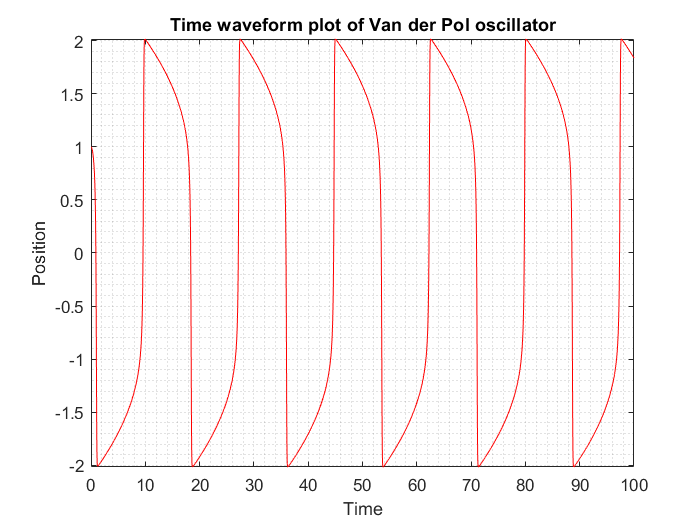

clf; figure(1);
plot(val.t,val.x,'r');
grid minor, xlabel('Time'), ylabel('Position')
title('Time waveform plot of Van der Pol oscillator')
axis([min(val.t) max(val.t) min(val.x) max(val.x)])

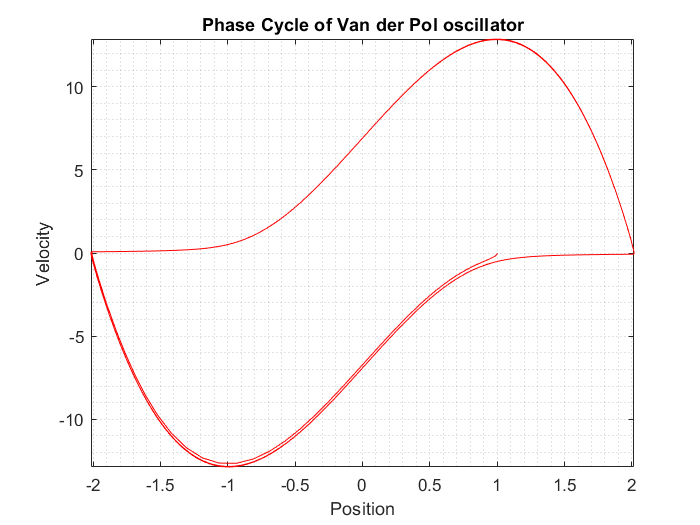

plot(val.x,val.Dx,'r')
grid minor, xlabel('Position'), ylabel('Velocity')
title('Phase Cycle of Van der Pol oscillator')
axis([min(val.x) max(val.x) min(val.Dx) max(val.Dx)])

### Part 2.2a: Comparing Different Mass Values

For varying values of masses:

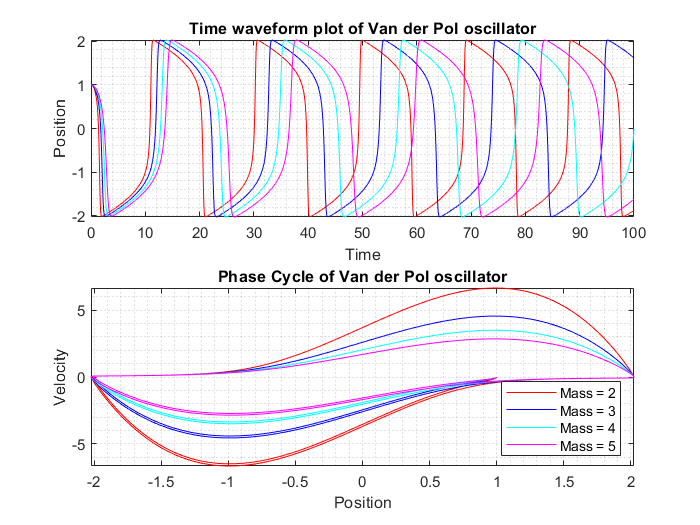

% Different values of mass with fixed force amplitude and mu:
mu = mu;                        % Unchanged mu value
m = 2:1:5;                      % Mass of 2 to 5
k = k;                          % Unchanged force amplitude

for n = 1:length(m)
    % Function handles:
    D2x_handle = @(t,x,Dx) mu*(1-x^2)*Dx/m(n) - k*x/m(n);% Setting d2x/dt2 = f(t,x,dx/dt)
    Dx_handle = @(t,x,Dx) Dx;                            % Setting dx/dt = g(t,x,dx/dt)

    % Evaluating Runge-Kutta on Van der Pol oscillator:
    out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
    val.t = out(1,:);               % Setting variable t for time values
    val.x(n,:) = out(2,:);          % Setting variable x for position values
    val.Dx(n,:) = out(3,:);         % Setting variable Dx for velocity values    
end

% Plotting the time waveform and phase cycle of different values of Mass
clf; figure(2);
subplot(2,1,1);
plot(val.t,val.x(1,:),'r',val.t,val.x(2,:),'b',val.t,val.x(3,:),'c',val.t,val.x(4,:),'m')
grid minor, xlabel('Time'), ylabel('Position')
title('Time waveform plot of Van der Pol oscillator')
axis([min(val.t) max(val.t) min(min(val.x)) max(max(val.x))])
subplot(2,1,2);
plot(val.x(1,:),val.Dx(1,:),'r',val.x(2,:),val.Dx(2,:),'b',val.x(3,:),val.Dx(3,:),'c',...
    val.x(4,:),val.Dx(4,:),'m')
grid minor, xlabel('Position'), ylabel('Velocity')
title('Phase Cycle of Van der Pol oscillator')
axis([min(min(val.x)) max(max(val.x)) min(min(val.Dx)) max(max(val.Dx))])
legend('Mass = 2','Mass = 3','Mass = 4','Mass = 5','Location','southeast')

The mass of the object changes the wavelength that: $m\propto \lambda$ where $\lambda =\textrm{wavelength}$.

### Part 2.2b: Comparing Different Force Values

For varying values of force amplitude:

% Different values of force amplitudes with fixed mass and mu:
mu = mu;                        % Unchanged mu value
m = 1;                          % Unchanged mass of 1
k = 2:1:5;                      % Force amplitude of 2 to 5

for n = 1:length(k)
    % Function handles:
    D2x_handle = @(t,x,Dx) mu*(1-x^2)*Dx/m - k(n)*x/m;  % Setting d2x/dt2 = f(t,x,dx/dt)
    Dx_handle = @(t,x,Dx) Dx;                           % Setting dx/dt = g(t,x,dx/dt)

    % Evaluating Runge-Kutta on Van der Pol oscillator:
    out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
    val.t = out(1,:);               % Setting variable t for time values
    val.x(n,:) = out(2,:);          % Setting variable x for position values
    val.Dx(n,:) = out(3,:);         % Setting variable Dx for velocity values    
end

% Plotting the time waveform and phase cycle of different values of Force Amplitude
clf; figure(3);

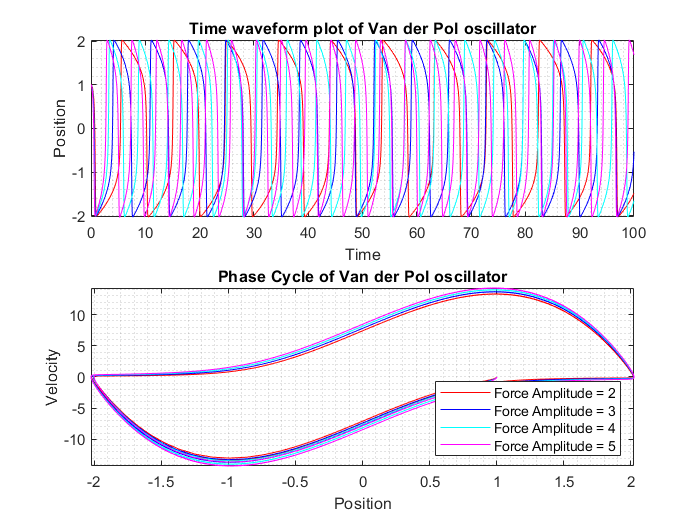

subplot(2,1,1);
plot(val.t,val.x(1,:),'r',val.t,val.x(2,:),'b',val.t,val.x(3,:),'c',val.t,val.x(4,:),'m')
grid minor, xlabel('Time'), ylabel('Position')
title('Time waveform plot of Van der Pol oscillator')
axis([min(val.t) max(val.t) min(min(val.x)) max(max(val.x))])
subplot(2,1,2);
plot(val.x(1,:),val.Dx(1,:),'r',val.x(2,:),val.Dx(2,:),'b',val.x(3,:),val.Dx(3,:),'c',...
    val.x(4,:),val.Dx(4,:),'m')
grid minor, xlabel('Position'), ylabel('Velocity')
title('Phase Cycle of Van der Pol oscillator')
axis([min(min(val.x)) max(max(val.x)) min(min(val.Dx)) max(max(val.Dx))])
legend('Force Amplitude = 2','Force Amplitude = 3','Force Amplitude = 4',...
    'Force Amplitude = 5','Location','southeast')

The force amplitude changes the wavelength that: $k\propto \frac{1}{\lambda }$ where $\lambda =\textrm{wavelength}$.

### Part 2.2c: Comparing Different $\mu$ Values

For varying values of $\mu$:

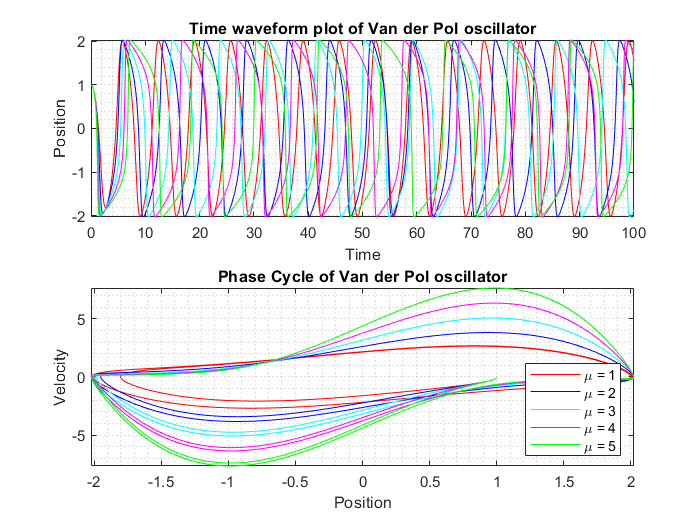

% Different values of force amplitudes with fixed mass and mu:
mu = 1:1:5;                     % Unchanged mu value
m = 1;                          % Unchanged mass of 1
k = 1;                          % Unchanged Force Amplitude of 1

for n = 1:length(mu)
    % Function handles:
    D2x_handle = @(t,x,Dx) mu(n)*(1-x^2)*Dx/m - k*x/m;  % Setting d2x/dt2 = f(t,x,dx/dt)
    Dx_handle = @(t,x,Dx) Dx;                           % Setting dx/dt = g(t,x,dx/dt)

    % Evaluating Runge-Kutta on Van der Pol oscillator:
    out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
    val.t = out(1,:);               % Setting variable t for time values
    val.x(n,:) = out(2,:);          % Setting variable x for position values
    val.Dx(n,:) = out(3,:);         % Setting variable Dx for velocity values    
end

% Plotting the time waveform and phase cycle of different values of mu
clf; figure(4);
subplot(2,1,1);
plot(val.t,val.x(1,:),'r',val.t,val.x(2,:),'b',val.t,val.x(3,:),'c',val.t,val.x(4,:),...
    'm',val.t,val.x(5,:),'g')
grid minor, xlabel('Time'), ylabel('Position')
title('Time waveform plot of Van der Pol oscillator')
axis([min(val.t) max(val.t) min(min(val.x)) max(max(val.x))])
subplot(2,1,2);
plot(val.x(1,:),val.Dx(1,:),'r',val.x(2,:),val.Dx(2,:),'b',val.x(3,:),val.Dx(3,:),'c',...
    val.x(4,:),val.Dx(4,:),'m',val.x(5,:),val.Dx(5,:),'g')
grid minor, xlabel('Position'), ylabel('Velocity')
title('Phase Cycle of Van der Pol oscillator')
axis([min(min(val.x)) max(max(val.x)) min(min(val.Dx)) max(max(val.Dx))])
legend('\mu = 1','\mu = 2','\mu = 3','\mu = 4','\mu = 5','Location','southeast')

Similar to the force amplitude, $\mu$ changes the wavelength that: $\mu \propto \frac{1}{\lambda }\;\textrm{where}\;\lambda =\textrm{wavelength}$.

### Part 2.3: Evaluating Van der Pol Oscillator using ODE45

For simplicity, the values of $m,k,\textrm{and}\;\mu$ are set to their default state: $m=k=\mu =1$

% Setting the parameter of the Van der Pol oscillator:
mu = 1;
m = 1;
k = 1;

Using the blackbox ODE solver, 'ode45', the values of time and position along with velocity can be solved.

% Using ode45 to solve Van der Pol oscillator:
[bb_val.t,bb_val.x] = ode45(@vdp1,[initial.t,final.t],[initial.x,initial.Dx]);

The time waveform plot of Van der Pol oscillator solved using 'ode45' is as shown along with the solution using fourth order Runge-Kutta:

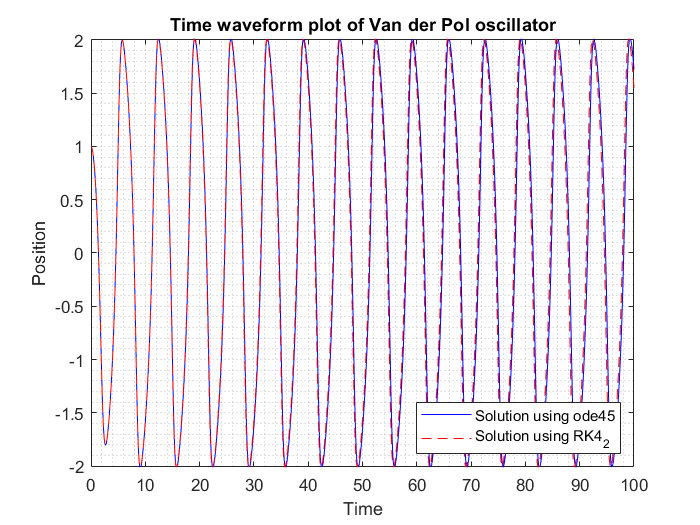

% Setting the function handle for the Van der Pol oscillator:
D2x_handle = @(t,x,Dx) mu*(1-x^2)*Dx/m - k*x/m;     % Setting d2x/dt2 = f(t,x,dx/dt)
Dx_handle = @(t,x,Dx) Dx;                           % Setting dx/dt = g(t,x,dx/dt)

% Evaluating Runge-Kutta on Van der Pol oscillator:
out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
val.t = out(1,:);           % Setting variable t for time values
val.x = out(2,:);           % Setting variable x for position values
val.Dx = out(3,:);          % Setting variable Dx for velocity values

% Plotting ode45 against RK4_2:
clf; figure(5);
plot(bb_val.t,bb_val.x(:,1),'b',val.t,val.x,'r--');
grid minor, xlabel('Time'), ylabel('Position')
title('Time waveform plot of Van der Pol oscillator')
legend('Solution using ode45','Solution using RK4_2','Location','southeast')
axis([min(val.t) max(val.t) min(val.x) max(val.x)])

For a small step size, the solutions do not seem to differ whether it is solved via 'ode45' or fourth order Runge-Kutta. However, for bigger step size, Runge-Kutta solution will be less accurate at solving the oscillator.

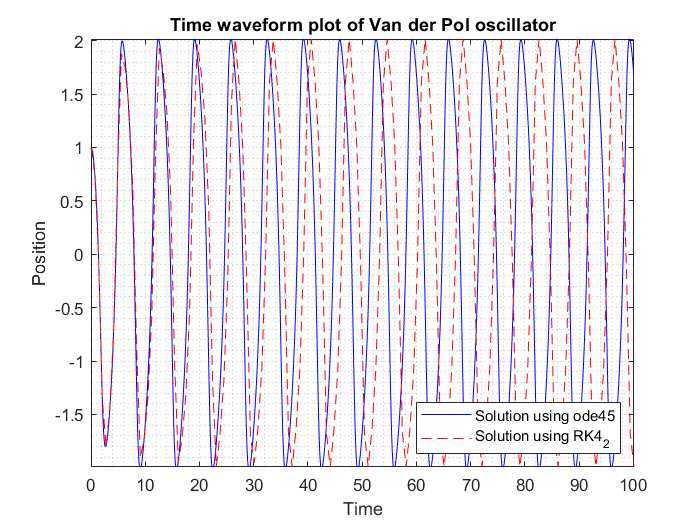

% Setting the step size:
Step_size = 0.7;            % Setting a different step size value

% Setting the function handle for the Van der Pol oscillator:
D2x_handle = @(t,x,Dx) mu*(1-x^2)*Dx/m - k*x/m;     % Setting d2x/dt2 = f(t,x,dx/dt)
Dx_handle = @(t,x,Dx) Dx;                           % Setting dx/dt = g(t,x,dx/dt)

% Evaluating Runge-Kutta on Van der Pol oscillator:
out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
val.t = out(1,:);           % Setting variable t for time values
val.x = out(2,:);           % Setting variable x for position values
val.Dx = out(3,:);          % Setting variable Dx for velocity values

% Plotting ode45 against RK4_2:
clf; figure(6);
plot(bb_val.t,bb_val.x(:,1),'b',val.t,val.x,'r--');
grid minor, xlabel('Time'), ylabel('Position')
title('Time waveform plot of Van der Pol oscillator')
legend('Solution using ode45','Solution using RK4_2','Location','southeast')
axis([min(val.t) max(val.t) min(val.x) max(val.x)])

In this case, the step size set on line 149 shows the discrepancy between Runge-Kutta solution and 'ode45' solution. It is shown that the bigger the step size, the solution found using Runge-Kutta is less accurate in a way that the wavelength is larger, hence: $\textrm{step}\;\textrm{size}\propto \lambda$.

### Part 2.4: Fourier Transform of the Steady State of the Waveform

For this part, a discrete Fourier transform will be used. The discrete Fourier transform is defined as:


$$X\left(k\right)=\sum_{n\;=\;0}^{N-1} x_n \;e^{-\textrm{i2}\frac{\pi }{N}kn}$$


where $k=\textrm{frequency}\;\frac{f}{N}$ and $\chi \left(k\right)=\textrm{signal}\;\textrm{in}\;\textrm{terms}\;\textrm{of}\;\textrm{frequency}$. An outside function, 'DFT.m', will be used to find the frequency-domain of the previous waveform. First, the parameters are reset to their default.

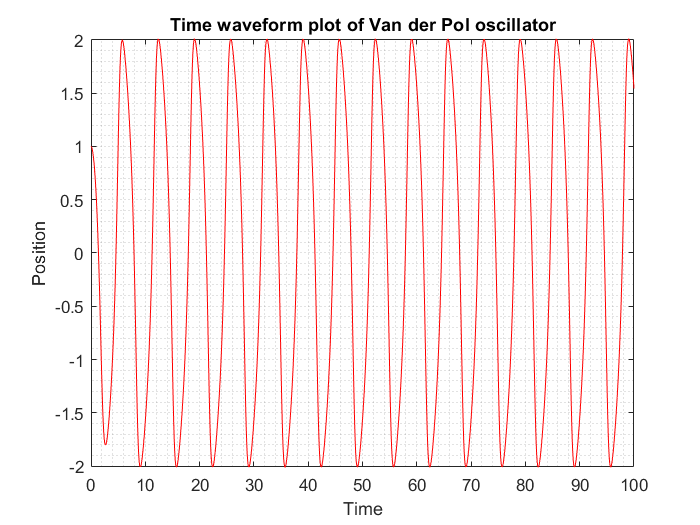

% Setting the step size:
Step_size = 0.01;          % Setting a different step size value

% Setting the function handle for the Van der Pol oscillator:
D2x_handle = @(t,x,Dx) mu*(1-x^2)*Dx/m - k*x/m;     % Setting d2x/dt2 = f(t,x,dx/dt)
Dx_handle = @(t,x,Dx) Dx;                           % Setting dx/dt = g(t,x,dx/dt)

% Evaluating Runge-Kutta on Van der Pol oscillator:
out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
val.t = out(1,:);           % Setting variable t for time values
val.x = out(2,:);           % Setting variable x for position values
val.Dx = out(3,:);          % Setting variable Dx for velocity values

% Plotting ode45 against RK4_2:
clf; figure(7);
plot(val.t,val.x,'r');
grid minor, xlabel('Time'), ylabel('Position')
title('Time waveform plot of Van der Pol oscillator')
axis([min(val.t) max(val.t) min(val.x) max(val.x)])

Next, the outside function 'DFT.m' is used to find the frequencies and the signal in terms of frequency, and then plotting the signal in terms of frequencies.

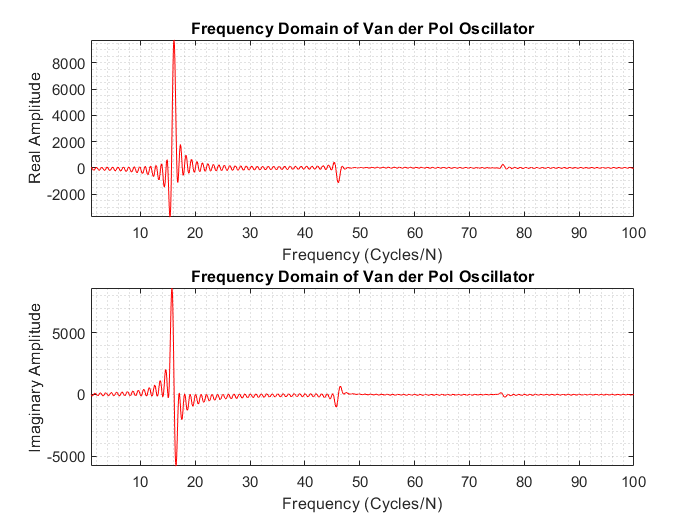

% Calling DFT.m to find Signal and Frequencies:
max_frequency = 100;                        % Maximum frequency
DFT_step = 0.01;                            % Step size for DFT
out = DFT(val.x,max_frequency,DFT_step);    % Discrete Fourier Transform
val.signal = out(1,:);                      % Signal output
val.freq = out(2,:);                        % Frequency output per length(position)

% Plotting the Fourier Transform of the steady-state waveform:
clf; figure(8);
subplot(2,1,1); plot(val.freq,real(val.signal),'r');
grid minor, xlabel('Frequency ({Cycles}/{N})'), ylabel('Real Amplitude')
title('Frequency Domain of Van der Pol Oscillator')
axis([min(val.freq) max(val.freq) min(real(val.signal)) max(real(val.signal))])
subplot(2,1,2); plot(val.freq,imag(val.signal),'r');
grid minor, xlabel('Frequency ({Cycles}/{N})'), ylabel('Imaginary Amplitude')
title('Frequency Domain of Van der Pol Oscillator')
axis([min(val.freq) max(val.freq) min(imag(val.signal)) max(imag(val.signal))])

### Part 2.4.1: Fourier Transform of Different Values of $\mu$

Given different values of $\mu$:

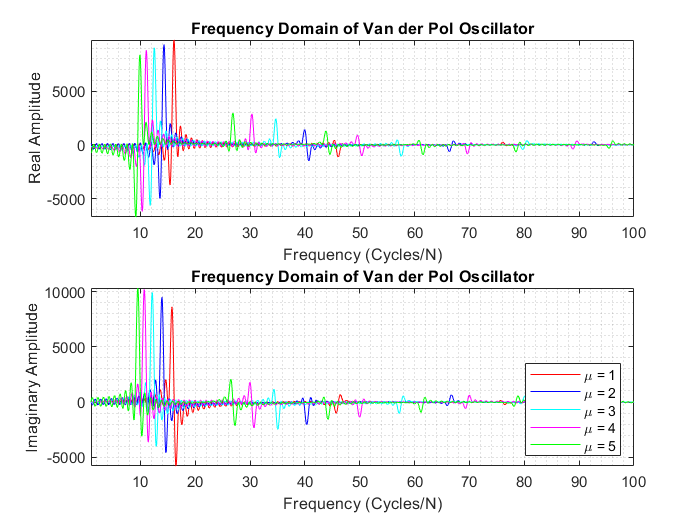

% Different values of force amplitudes with fixed mass and mu:
mu = 1:1:5;                     % Unchanged mu value
m = 1;                          % Unchanged mass of 1
k = 1;                          % Unchanged Force Amplitude of 1
max_frequency = 100;            % Maximum frequency

for n = 1:length(mu)
    % Function handles:
    D2x_handle = @(t,x,Dx) mu(n)*(1-x^2)*Dx/m - k*x/m;  % Setting d2x/dt2 = f(t,x,dx/dt)
    Dx_handle = @(t,x,Dx) Dx;                           % Setting dx/dt = g(t,x,dx/dt)

    % Evaluating Runge-Kutta on Van der Pol oscillator:
    out = RK4_2(initial.t,initial.x,initial.Dx,Step_size,final.t,D2x_handle,Dx_handle);
    val.t = out(1,:);               % Setting variable t for time values
    val.x(n,:) = out(2,:);          % Setting variable x for position values
    val.Dx(n,:) = out(3,:);         % Setting variable Dx for velocity values
    
end

for n = 1:length(mu)
    % Calling DFT.m to find Signal and Frequencies:
    out = DFT(val.x(n,:),max_frequency,DFT_step);% Discrete Fourier Transform
    val.signal(n,:) = out(1,:);                  % Signal output
    val.freq(n,:) = out(2,:);          % Frequency output per length(position)
end

% Plotting the Frequency Domain:
clf; figure(9);

subplot(2,1,1); 
plot(val.freq(1,:),real(val.signal(1,:)),'r',val.freq(2,:),...
    real(val.signal(2,:)),'b',val.freq(3,:),real(val.signal(3,:)),...
    'c',val.freq(4,:),real(val.signal(4,:)),'m',val.freq(5,:),...
    real(val.signal(5,:)),'g');
grid minor, xlabel('Frequency (Cycles/N)'), ylabel('Real Amplitude')
title('Frequency Domain of Van der Pol Oscillator')
axis([min(min(val.freq)) max(max(val.freq)) min(min(real(val.signal))) ...
    max(max(real(val.signal)))])

subplot(2,1,2); 
plot(val.freq(1,:),imag(val.signal(1,:)),'r',val.freq(2,:),...
    imag(val.signal(2,:)),'b',val.freq(3,:),imag(val.signal(3,:)),...
    'c',val.freq(4,:),imag(val.signal(4,:)),'m',val.freq(5,:),...
    imag(val.signal(5,:)),'g');
grid minor, xlabel('Frequency (Cycles/N)'), ylabel('Imaginary Amplitude')
title('Frequency Domain of Van der Pol Oscillator')
axis([min(min(val.freq)) max(max(val.freq)) min(min(imag(val.signal))) ...
    max(max(imag(val.signal)))])
legend('\mu = 1','\mu = 2','\mu = 3','\mu = 4','\mu = 5','Location','southeast')

Looking at the graph above, the peak of the amplitude happens in smaller frequency as $\mu$ value goes up.

## Part 3: Transfer Function of RC Highpass Filter

Given RC Highpass filter:

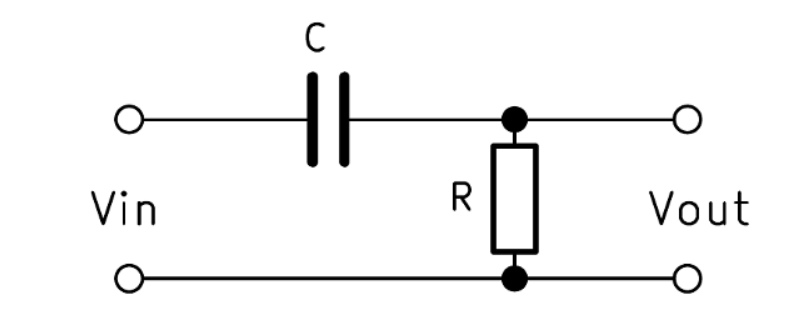

the input impedance is:


$$Z=\sqrt{R^2 -\frac{1}{{\left(2\pi fC\right)}^2 }}$$


and the transfer function for the RC Highpass filter is:


$$\frac{V_{\textrm{out}} }{V_{\textrm{in}} }={\sqrt{1+{\left(2\pi fRC\right)}^{-2} }}^{-1}$$


where $f=\textrm{frequency}\;\textrm{in}\;\textrm{Hertz}$, $R=\textrm{Resistance}\;\textrm{in}\;\Omega$, and $C=\textrm{Capacitance}\;\textrm{in}\;\textrm{Farads}$. The input impedance and transfer function derivation of the highpass filter can be obtained from (I do not have the rquired knowledge to evaluate electronic components, hence I do not know how to derive such equations):

- [http://sites.fas.harvard.edu/~phys123/classnotes/class2_notes_headerfile_rev_july14.pdf](http://sites.fas.harvard.edu/~phys123/classnotes/class2_notes_headerfile_rev_july14.pdf)

- [https://electronicbase.net/high-pass-filter-calculator/](https://electronicbase.net/high-pass-filter-calculator/)

- [http://ecee.colorado.edu/~mathys/ecen2260/pdf/review01.pdf](http://ecee.colorado.edu/~mathys/ecen2260/pdf/review01.pdf)

### Part 3.1: Plotting the Transform Function

For different sets of $R$ and $C$ values, the transfer function can be plotted in terms of the frequency $f$. The plots that can be produced:


$$H\left(f\right)=\frac{V_{\textrm{out}} \left(t\right)}{V_{\textrm{in}} \left(t\right)}={\sqrt{1+{\left(2\pi fRC\right)}^{-2} }}^{-1}$$


The plot that will be produced is $H\left(f\right)$ with different sets of $RC$ values. This also shows the frequency domain of the signal.

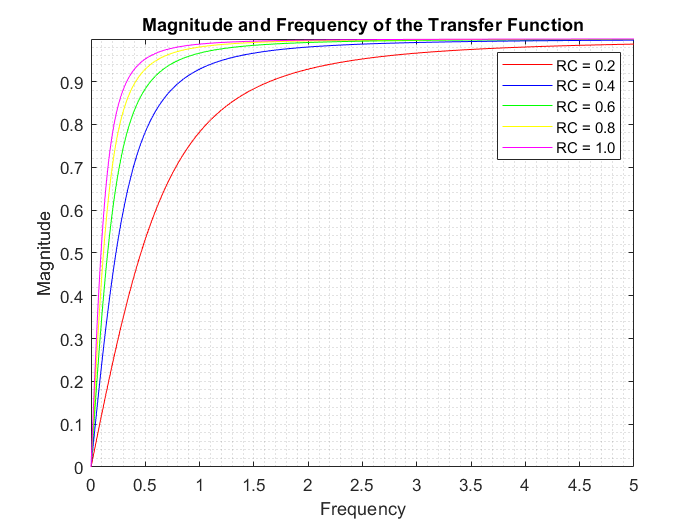

% Clearing the memory
clear; clc; clf;

% Setting up the parameters of the transfer function:
f = 0:0.01:5;               % Frequency parameter
RC = 0.2:0.2:1;             % R and C parameters

% Transfer function with different sets of R and C values:
for n = 1:length(RC)
    H(n,:) = sqrt(1+(2*pi*RC(n)*f).^(-2)).^(-1);
end

% Plotting transfer function for different sets of R and C values:
clf; figure();
plot(f,H(1,:),'r',f,H(2,:),'b',f,H(3,:),'g',f,H(4,:),'y',f,H(5,:),'m');
grid minor, xlabel('Frequency'), ylabel('Magnitude')
title('Magnitude and Frequency of the Transfer Function')
axis([min(f) max(f) min(min(H)) max(max(H))])
legend('RC = 0.2','RC = 0.4','RC = 0.6','RC = 0.8','RC = 1.0',...
    'Location','northeast')

### Part 3.2: Signal Filteration

For a broadband signal $x\left(t\right)$, the associated Fourier transform will be determined. One method to do this is to use an outside function 'DFT.m', which is the discrete Fourier transform function used in previous parts. This function inputs a set of data and outputs the frequencies and the frequency domain of said data within a range of frequencies.

Using a broadband signal consisting of the sum of multiple sinusoids and a noise factor:


$$x\left(t\right)=\sum_{i\;=1}^N a_i \cos \left(n_i t+\Phi_i \right)+\textrm{noise}\left(t\right)$$


where $a_i =\textrm{amplitude}\;\textrm{of}\;\textrm{sinusoid}\;i$, $n_i =\textrm{frequency}\;\textrm{factor}\;\textrm{of}\;\textrm{sinusoid}\;i$, $\Phi_i =\textrm{phase}\;\textrm{shift}\;\textrm{of}\;\textrm{sinusoid}\;i$, and a noise factor, the frequency domain of said signal can be determined using DFT. In mathematical sense, the frequency domain of the signal for discrete values of $x$ is:


$$X\left(f\right)=\sum_{n\;=\;0}^{N-1} x_n \;e^{-\textrm{i2}\frac{\pi }{N}kn}$$


where $x_n$ is a discrete set of values from the signal $x\left(t\right)$.

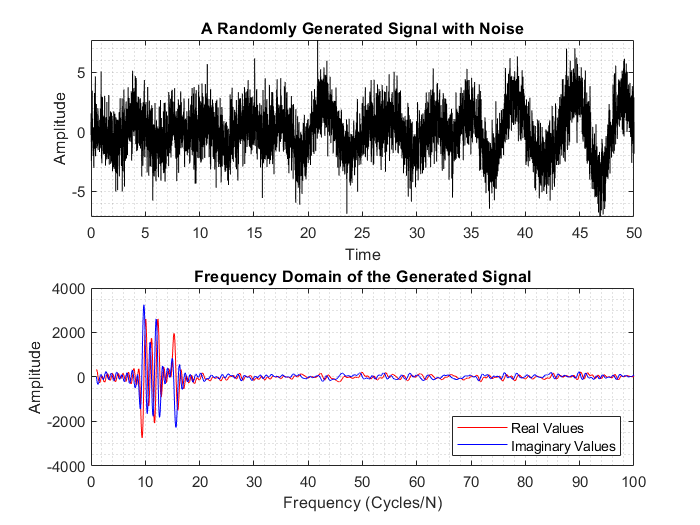

% Setting the parameters for random signal:
max_amplitude = 1;  % The max amplitude a sinusoid can have
t_range = [0 50];   % The range of time in which the signal is generated
t_step = 0.01;      % The step size for time

% Using an outside function 'rand_signal' to generate a random signal:
signal.func = rand_signal(t_range,t_step,max_amplitude,1);
signal.t = signal.func(1,:);
signal.x = signal.func(2,:);

% Setting the parameter for DFT:
max_frequency = 100;
DFT_step = 0.01;

% Frequency domain of the signal:
domain.freq = DFT(signal.x,max_frequency,DFT_step);
domain.fx = domain.freq(1,:);       % Chi values
domain.fk = domain.freq(2,:);       % Frequency values

% Plotting the signal
clf; figure();
subplot(2,1,1);
plot(signal.t,signal.x,'k');
grid minor, xlabel('Time'), ylabel('Amplitude')
title('A Randomly Generated Signal with Noise')
axis([min(signal.t) max(signal.t) min(signal.x) max(signal.x)])

% Plotting the frequency domain
subplot(2,1,2);
plot(domain.fk,real(domain.fx),'r',domain.fk,imag(domain.fx),'b');
grid minor, xlabel('Frequency (Cycles/N)'), ylabel('Amplitude'),
title('Frequency Domain of the Generated Signal')
legend('Real Values','Imaginary Values','Location','southeast')

### Part 3.2a: Spectral Domain Filtering

The spectral domain filtering is evaluated by:


$$\textrm{Spectral}\left(f\right)=X\left(f\right)H\left(f\right)$$


which is the product of the frequency domain of the signal and the transfer function.

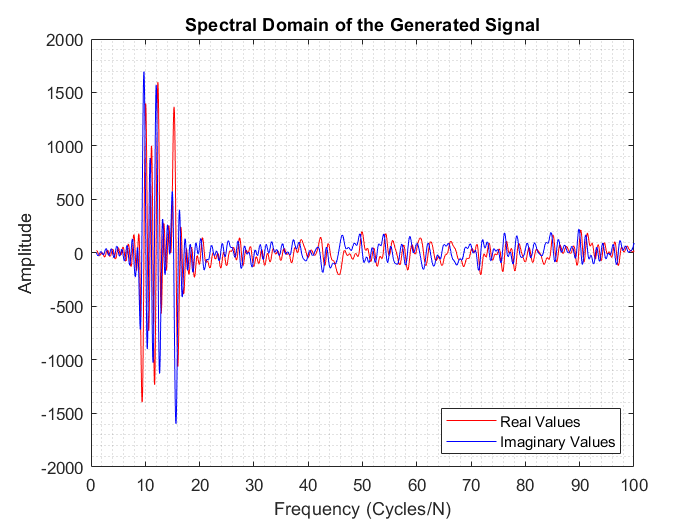

% Setting the transfer function
RC = 0.01;       % Setting the R and C values

% Transfer function:
H = sqrt(1+(2*pi*RC*domain.fk).^(-2)).^(-1);

% Spectral Domain:
domain.sp = H.*domain.fx;
% Plotting the Spectral Domain
clf; figure();
plot(domain.fk,real(domain.sp),'r',domain.fk,imag(domain.sp),'b')
grid minor, xlabel('Frequency (Cycles/N)'), ylabel('Amplitude')
title('Spectral Domain of the Generated Signal')
legend('Real Values','Imaginary Values','Location','southeast')

### Part 3.2b: Temporal Domain Filtering

The Temporal Domain Filtering is evaluated by:


$$\mathrm{Temporal}\left(t\right)=x\left(t\right)\otimes X^{-1} \left(H\left(f\right)\right)$$


where $\otimes$ is a convolution operator and $X^1 \left(H\left(f\right)\right)$ represents the inverse Fourier transform of the transfer function. The inverse discrete Fourier function of the transfer function is:


$$x\left(t\right)=\frac{1}{N}\sum_{k\;=\;0}^{N-1} X\left(f\right)\bullet \exp \left(\textrm{i2}\pi \frac{k}{N}n\right)$$


where $X\left(f\right)=H\left(f\right)$. The outside function 'inv_DFT.m' is used to evaluate the inverse DFT and the outside function 'convolute.m' the convolution.

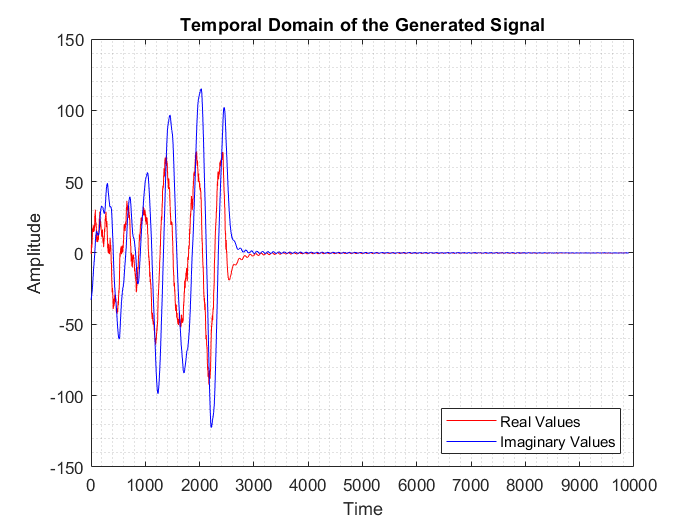

% Setting the inverse DFT
out = inv_DFT(H,max_frequency,DFT_step);
domain.tx = out(1,:);
domain.tt = out(2,:);

% Convoluting x and X^-1(H):
domain.tx = conv(domain.tx,signal.x,'same');
% Plotting the Temporal Domain
clf; figure();
plot(domain.tt,real(domain.tx),'r',domain.tt,imag(domain.tx),'b')
grid minor, xlabel('Time'), ylabel('Amplitude')
title('Temporal Domain of the Generated Signal')
legend('Real Values','Imaginary Values','Location','southeast')

### Part 3.2c: Putting the two Together

A confusing part of this part of the assignment is that the temporal domain and the spectral domain should be plotted together, but they do not have the same units for their variables. The spectral domain depends on frequency while the convoluted temporal domain depends on time. One way to do this to to graph the frequency domain of the convoluted signal.

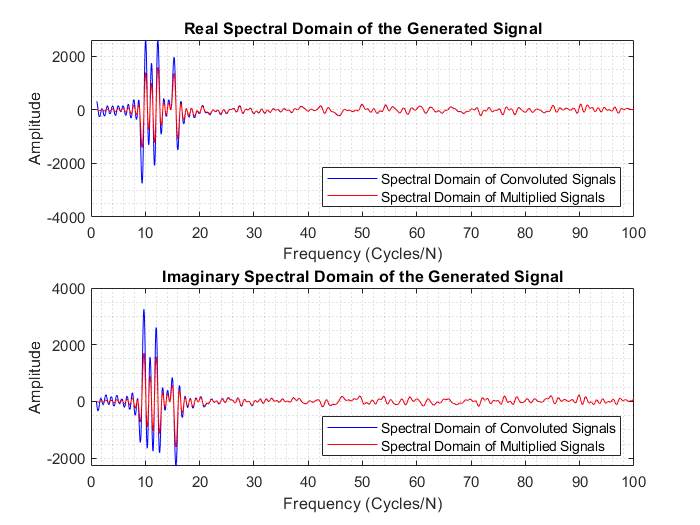

% Frequency domain of the signal:
domain.freq2 = DFT(domain.tx,max_frequency,DFT_step);
domain.fx2 = domain.freq(1,:);      % Chi values
domain.fk2 = domain.freq(2,:);      % Frequency values

% Plotting the Spectral Domain
clf; figure();
subplot(2,1,1)
plot(domain.fk2,real(domain.fx2),'b',domain.fk,real(domain.sp),'r')
grid minor, xlabel('Frequency (Cycles/N)'), ylabel('Amplitude')
title('Real Spectral Domain of the Generated Signal')
legend('Spectral Domain of Convoluted Signals',...
    'Spectral Domain of Multiplied Signals','Location','southeast')

subplot(2,1,2)
plot(domain.fk2,imag(domain.fx2),'b',domain.fk,imag(domain.sp),'r')
grid minor, xlabel('Frequency (Cycles/N)'), ylabel('Amplitude')
title('Imaginary Spectral Domain of the Generated Signal')
legend('Spectral Domain of Convoluted Signals',...
    'Spectral Domain of Multiplied Signals','Location','southeast')

Despite not having the same amplitude, both signals line up perfectly in the given frequency range. This approach shows the *convolution theorem*.

## Part 4: Hilbert Transform

For two randomly generated signals consisting of the sums of multiple sinusoids and additive noise, one of which has a $\textrm{SNR}=\infty \;\textrm{dB}$ and the other $\textrm{SNR}=20\;\textrm{dB}$. In Decibels, the SNR is obtained by:


$$\textrm{SNR}=10\log_{10} \left(\frac{P_{\textrm{signal}} }{P_{\textrm{noise}} }\right)$$


where $P=\textrm{power}$ and is defined by:


$$P_x =\frac{1}{N}\sum_{n\;=1}^N \left|x\left(n\right){\left|\right.}^2 \right.$$


Hence:


$$\textrm{SNR}=10\log_{10} \left(\sum_{n\;=1}^N \frac{\left|\textrm{signal}\left(n\right){\left|\right.}^2 \right.}{\left|\textrm{noise}\left(n\right){\left|\right.}^2 \right.}\right)$$


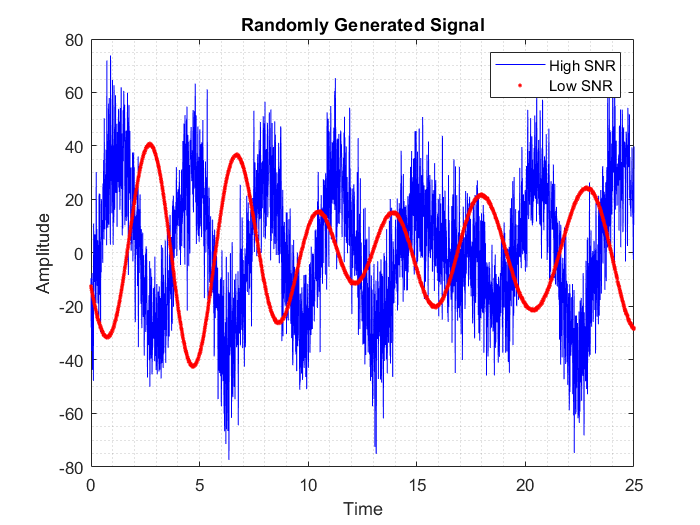

% Clearing the memory
clear; clc; clf;

% Setting a parameter for the signal:
t_range = [0 25];   % Time range for the signal
t_step = 0.01;      % Time step size
max_amplitude = 20; % Max amplitude for signal

% Setting the first signal with low noise:
noise_power = max_amplitude/100;      % Noise power for high SNR
out = rand_signal(t_range,t_step,max_amplitude,0);
for n = 1:length(out(2,:))
    noise(n) = noise_power*randn(1);
    out(2,n) = out(2,n) + noise(n);
end
signal.t = out(1,:);
signal.x1 = out(2,:);

% Setting the second signal with high noise:
noise_power = 15;      % Noise power for high SNR
out = rand_signal(t_range,t_step,max_amplitude,0);
for n = 1:length(out(2,:))
    noise(n) = noise_power*randn(1);
    out(2,n) = out(2,n) + noise(n);
end
signal.x2 = out(2,:);

% Plotting the signal:
clf; figure();
plot(signal.t,signal.x2,'b',signal.t,signal.x1,'r.')
grid minor, xlabel('Time'), ylabel('Amplitude')
title('Randomly Generated Signal')
legend('High SNR','Low SNR')

To compute the Hilbert transform of the previous signals, MATLAB built in function 'hilbert.m'. MATLAB built in function 'hilbert' works as follows:

- Do the FFT of Xr. 

- Set the elements in FFT which correspond to frequency −π < ω < 0 to zero. 

- Do the inverse FFT.

The function outputs $X=x_r +{ix}_i$ where $x_r =\mathrm{input}\;\mathrm{signal}$ and $x_i =\mathrm{Hilbert}\;\mathrm{Transformed}\;\mathrm{Signal}$. This is a confusing nature as the output of 'hilbert' is not actually the transformed signal, but rather the original signal plus the imaginary of the transformed signal.

To see the result, the signal will be superimposed with the transformation.

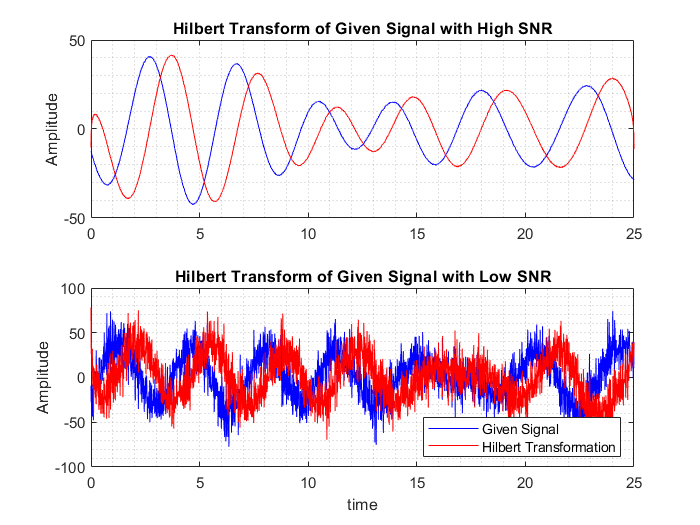

% Hilbert transformation of the two signals:
signal.h1 = hilbert(signal.x1);
signal.h2 = hilbert(signal.x2);

% Plotting the Hilbert transformations:
clf; figure();
subplot(2,1,1)
plot(signal.t,signal.x1,'b',signal.t,imag(signal.h1),'r')
grid minor, ylabel('Amplitude')
title('Hilbert Transform of Given Signal with High SNR')
subplot(2,1,2)
plot(signal.t,signal.x2,'b',signal.t,imag(signal.h2),'r')
grid minor, xlabel('time'), ylabel('Amplitude')
title('Hilbert Transform of Given Signal with Low SNR')
legend('Given Signal','Hilbert Transformation','Location','southeast')

Using the built in function 'hilbert' for Hilbert Transformation, it can be seen that the Hilbert Transformation introduce a shift in x, roughly a $\frac{\pi }{4}$ to the right in this case. What happens when the signal are 'corrected' so they lie on top of one another?

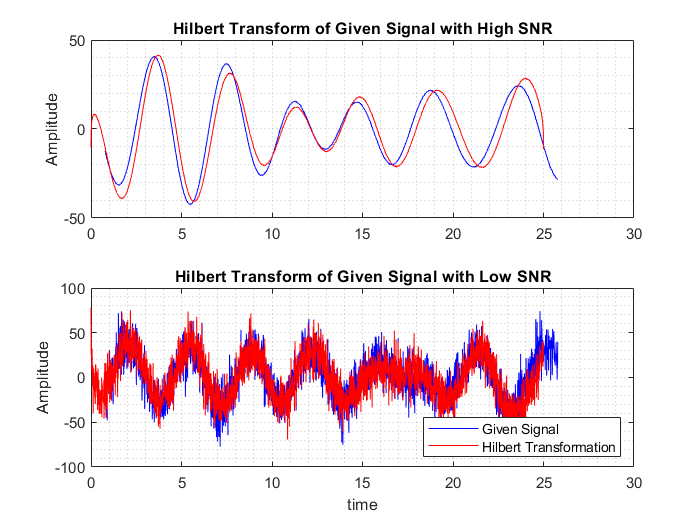

% Plotting the Hilbert transformations (shifted):
clf; figure();
subplot(2,1,1)
plot(signal.t + pi/4,signal.x1,'b',signal.t,imag(signal.h1),'r')
grid minor, ylabel('Amplitude')
title('Hilbert Transform of Given Signal with High SNR')
subplot(2,1,2)
plot(signal.t + pi/4,signal.x2,'b',signal.t,imag(signal.h2),'r')
grid minor, xlabel('time'), ylabel('Amplitude')
title('Hilbert Transform of Given Signal with Low SNR')
legend('Given Signal','Hilbert Transformation','Location','southeast')

It can be seen that the signal almost lines up, but not quite. The peaks of the signal with high SNR do not match in time, but it may be the shifting error. The signal with low SNR does not seem to have any differences with the base signal, but it does have a slightly different noise compared to its transformation.